clear 
close all

**Exercise 3.1.1.** Calculate the transfer matrix G(s). Investigate each element of the

matrix (Hint: G(1,1) extracts element (1,1)). Calculate the poles and zeros of the

elements.


$$G(s) = C(s)(sI-A)^{-1}B + D =  \frac{1}{det(sI-A) }* r(s)$$


sys_m = minphase

sys_m =
 
  A = 
             x1        x2        x3        x4
   x1  -0.05645         0   0.02572         0
   x2         0  -0.05187         0    0.0213
   x3         0         0  -0.02572         0
   x4         0         0         0   -0.0213
 
  B = 
            u1       u2
   x1    0.174        0
   x2        0   0.1506
   x3        0  0.09038
   x4   0.1044        0
 
  C = 
        x1   x2   x3   x4
   y1  0.2    0    0    0
   y2    0  0.2    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.




% The system transfer matrix
G_m = tf(sys_m)

G_m =
 
  From input 1 to output...
         0.0348
   1:  -----------
       s + 0.05645
 
               0.0004446
   2:  --------------------------
       s^2 + 0.07317 s + 0.001105
 
  From input 2 to output...
               0.0004649
   1:  --------------------------
       s^2 + 0.08217 s + 0.001452
 
         0.03013
   2:  -----------
       s + 0.05187
 
Continuous-time transfer function.




% Poles of the individual elements
p_11 = pole(G_m(1,1))

p_11 = -0.0564

p_12 = pole(G_m(1,2))

p_12 =    -0.0564
   -0.0257


p_21 = pole(G_m(2,1))

p_21 =    -0.0519
   -0.0213


p_22 = pole(G_m(2,2))

p_22 = -0.0519

**Exercise 3.1.2.** Calculate the poles and zeros of the multivariable system. Do these

imply any constraint on the achievable control performance?

% Poles of G
e_m = eig(sys_m.a)

e_m =    -0.0564
   -0.0519
   -0.0257
   -0.0213



% Zeros of G
G_z_m = G_m(1,1) * G_m(2,2) - G_m(1,2) * G_m(2,1);

tzero(G_z_m)

ans =    -0.0564
   -0.0519
   -0.0377
   -0.0093


No RHP poles or zeros that imply any restrictions. 

**Exercise 3.1.3.** Investigate the largest and smallest singular values for the system at

different frequencies. Calculate the $H_{\infty}
$norm of the system.

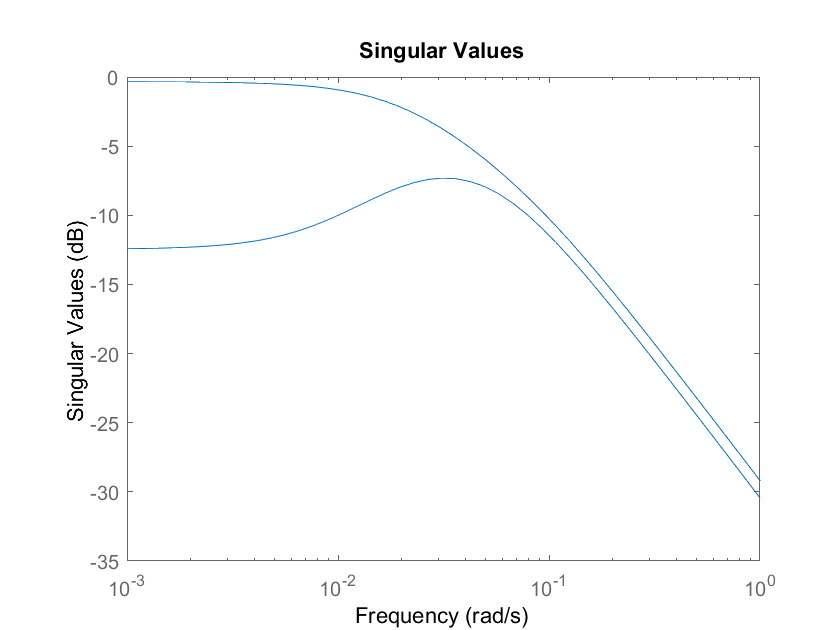

figure
sigma(sys_m.a, sys_m.b, sys_m.c, sys_m.d)


% Singular values at frequency 0
[U_m,S_m,V_m] = svd(evalfr(G_m,0))

U_m =    -0.7003   -0.7139
   -0.7139    0.7003


S_m =     0.9619         0
         0    0.2382


V_m =    -0.7476   -0.6642
   -0.6642    0.7476


**Exercise 3.1.4**. Investigate the RGA of the system at frequency 0. What conclusions

can we draw about the possibility of using decentralized control?

RGA = Relative Gain Array

pair u_i and y_j if RGA(G($\omega_c$)ij ~1 

avoid paring of u_i and y_j if RGA(G(0))ij < 0 

RGA = evalfr(G_m,0) .* inv(evalfr(G_m,0))'

RGA =     1.5625   -0.5625
   -0.5625    1.5625


omega_c_m = 0.1;
i = sqrt(-1);
RGA = evalfr(G_m,i*omega_c_m) .* inv(evalfr(G_m,i*omega_c_m))'

RGA =   -0.5013 - 0.8462i   0.0087 + 0.0162i
   0.0111 + 0.0147i  -0.5599 - 0.8086i


Here we can se that the cross terms$\lambda_{12}
$ are negative when evaluated at 0. Hence we choose not to pair $u_1 $ and $y_2
$ but instead $u_1 
$with $y_1$ and $u_2$ with $y_2$. 

**Exercise 3.1.5.** Plot the step response for one input at the time. Investigate the

outputs: Is the system coupled? Is this in line with the properties of RGA?

- The system should be coupled since the cross terms in G(s) is non-zero.

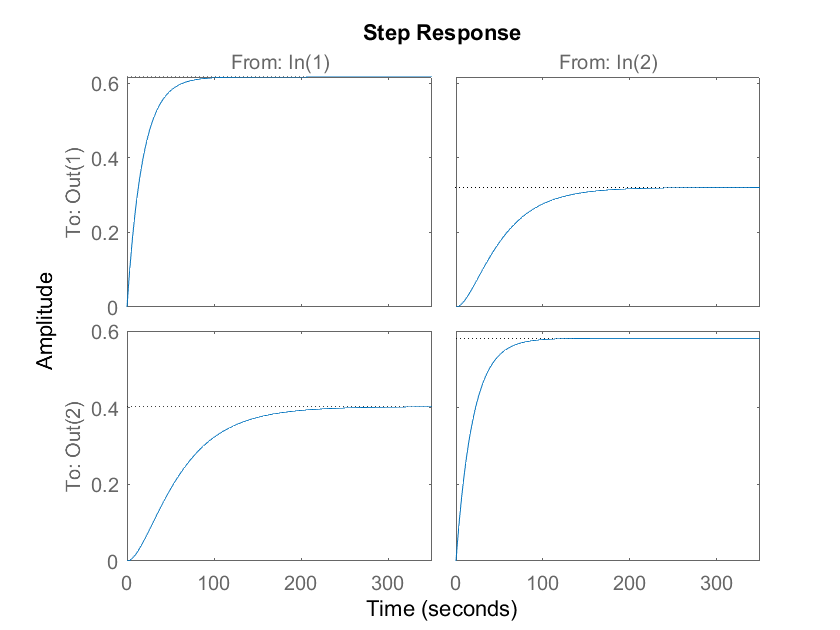

figure
step(G_m)

In the step plot one can clearly see that a step in $u_1$results in a response in $y_2
$ and vice versa. This confirms the earlier belief.

## **Now solve the above problems above for the non-minimum phase case**

**Exercise 3.1.1.NP** Calculate the transfer matrix G(s). Investigate each element of the

matrix (Hint: G(1,1) extracts element (1,1)). Calculate the poles and zeros of the

elements.


$$G(s) = C(s)(sI-A)^{-1}B + D =  \frac{1}{det(sI-A) }* r(s)$$


sys_nm = nonminphase

sys_nm =
 
  A = 
             x1        x2        x3        x4
   x1  -0.05106         0   0.08582         0
   x2         0  -0.04692         0   0.09089
   x3         0         0  -0.08582         0
   x4         0         0         0  -0.09089
 
  B = 
            u1       u2
   x1   0.1044        0
   x2        0  0.09038
   x3        0   0.1506
   x4    0.174        0
 
  C = 
        x1   x2   x3   x4
   y1  0.2    0    0    0
   y2    0  0.2    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.




% The system transfer matrix
G_nm = tf(sys_nm)

G_nm =
 
  From input 1 to output...
         0.02088
   1:  -----------
       s + 0.05106
 
               0.003163
   2:  -------------------------
       s^2 + 0.1378 s + 0.004265
 
  From input 2 to output...
               0.002586
   1:  -------------------------
       s^2 + 0.1369 s + 0.004382
 
         0.01808
   2:  -----------
       s + 0.04692
 
Continuous-time transfer function.




% Poles of the individual elements
p_11_nm = pole(G_nm(1,1))

p_11_nm = -0.0511

p_12_nm = pole(G_nm(1,2))

p_12_nm =    -0.0858
   -0.0511


p_21_nm = pole(G_nm(2,1))

p_21_nm =    -0.0909
   -0.0469


p_22_nm = pole(G_nm(2,2))

p_22_nm = -0.0469

**Exercise 3.1.2.NP** Calculate the poles and zeros of the multivariable system. Do these

imply any constraint on the achievable control performance?

% Poles of G_nm
e_nm = eig(sys_nm.a)

e_nm =    -0.0511
   -0.0469
   -0.0858
   -0.0909



% Zeros of G
G_z_nm = G_nm(1,1) * G_nm(2,2) - G_nm(1,2) * G_nm(2,1);
tzero(G_z_nm)

ans =    -0.2356
    0.0589
   -0.0511
   -0.0469


No RHP poles or zeros that imply any restrictions. 

**Exercise 3.1.3.NP **Investigate the largest and smallest singular values for the system at

different frequencies. Calculate the $H_{\infty}
$norm of the system.

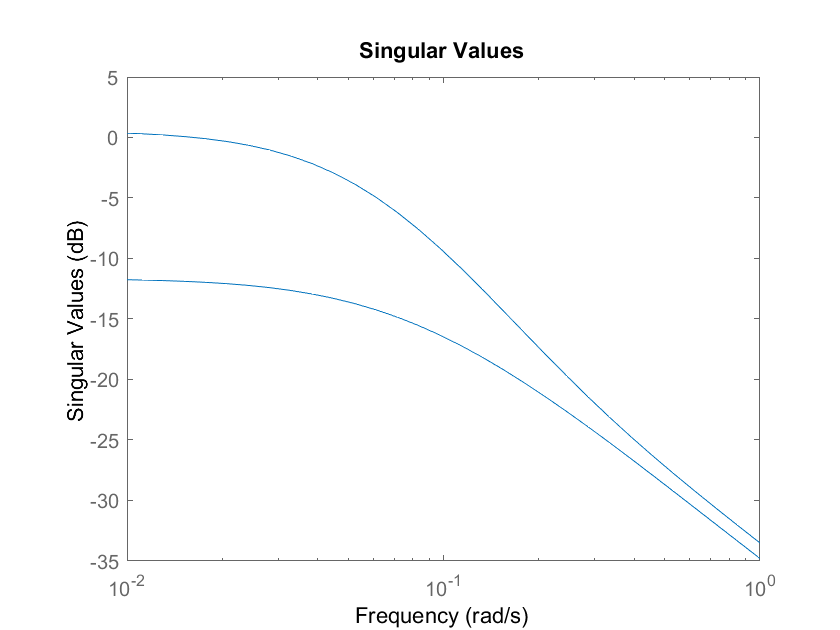

figure
sigma(sys_nm.a, sys_nm.b, sys_nm.c, sys_nm.d)


% Singular values at frequency 0
[U_nm,S_nm,V_nm] = svd(evalfr(G_nm,0))

U_nm =    -0.6442   -0.7649
   -0.7649    0.6442


S_nm =     1.0702         0
         0    0.2617


V_nm =    -0.7762    0.6305
   -0.6305   -0.7762


**Exercise 3.1.4**.**NP** Investigate the RGA of the system at frequency 0. What conclusions

can we draw about the possibility of using decentralized control?

RGA = Relative Gain Array

pair u_i and y_j if RGA(G($\omega_c$))ij ~1 

avoid paring of u_i and y_j if RGA(G(0))ij < 0 

RGA = evalfr(G_nm,0) .* inv(evalfr(G_nm,0))'

RGA =    -0.5625    1.5625
    1.5625   -0.5625


omega_c_nm = 0.2;
i = sqrt(-1);
RGA = evalfr(G_nm,i*omega_c_nm) .* inv(evalfr(G_nm,i*omega_c_nm))'

RGA =   -0.5424 - 0.5065i   0.2506 + 0.2243i
   0.2499 + 0.2251i  -0.5617 - 0.4849i


Here we can se that the cross terms$\lambda_{12}
$ are positive when evaluated at 0. Hence we choose to pair $u_1 $ and $y_2
$ instead of $u_1 
$with $y_1$ and $u_2$ with $y_2$. 

**Exercise 3.1.5.NP** Plot the step response for one input at the time. Investigate the

outputs: Is the system coupled? Is this in line with the properties of RGA?

- The system should be coupled since the cross terms in G(s) is non-zero.

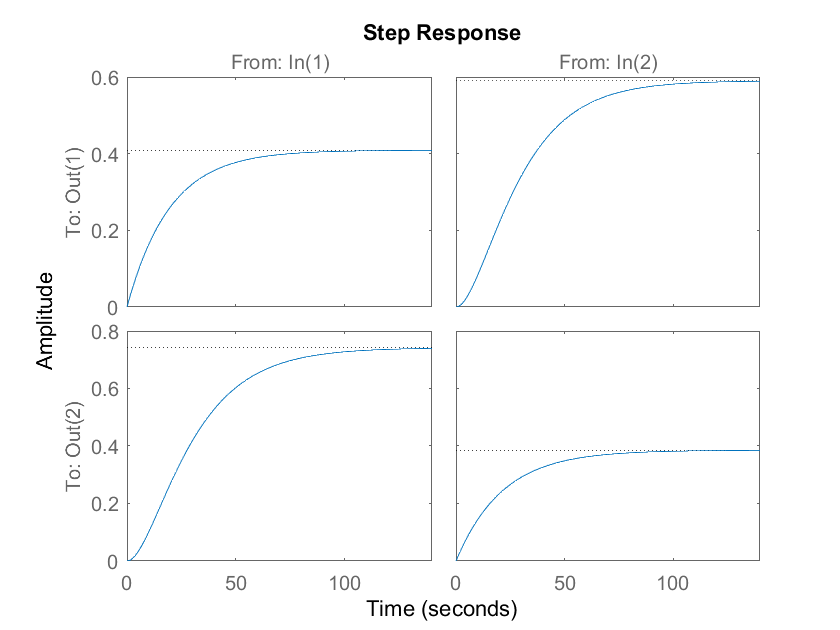

figure
step(G_nm)

In the step plot one can still clearly see that a step in $u_1$results in a response in $y_2
$ and vice versa. This once again confirms the earlier belief.

**Exercise 3.1.6.** Describe the most important differences between the two cases and

discuss how it affects the control performance.

The biggest difference is that in the non-minimum phase case the coupling is stronger and the input $u_1$ affects $y_2$ more than it affects $y_1$.

## 3.2 Decentralized control

**Exercise 3.2.1.** Design a decentralized controller by pairing inputs and outputs according

to the RGA analysis. The intended phase margin is 'm = $\phi_m$/3 and the crossover

frequency !c is 0.1 rad/s for the minimum phase case and 0.02 rad/s for the

non-minimum phase case. (To make sure that the problem is correctly solved, investigate

the Bode diagram of L.)

sys_m = minphase;

% Desired phase and crossover freq
pm = pi/3;
wc_m = 0.1;  

s = tf('s');

G_m = tf(sys_m);

[~, ph_11_m] = bode(G_m(1,1), wc_m);
[~, ph_21_m] = bode(G_m(2,2), wc_m);

Ti_1_m = 1/wc_m*tan(-pi+pi/2+pm-ph_11_m*pi/180);
Ti_2_m = 1/wc_m*tan(-pi+pi/2+pm-ph_21_m*pi/180);

l11_m = G_m(1,1)*(1+1/(s*Ti_1_m));
l22_m = G_m(2,2)*(1+1/(s*Ti_2_m));

[l11_wc_m, ~] = bode(l11_m, wc_m);
[l22_wc_m, ~] = bode(l22_m, wc_m);

K1_m = 1/abs(l11_wc_m);
K2_m = 1/abs(l22_wc_m);

f1_m = K1_m*(1+1/(s*Ti_1_m));
f2_m = K2_m*(1+1/(s*Ti_2_m));

F_m = [f1_m, 0; 0, f2_m];
L_m = minreal(G_m*F_m);

Plot the results

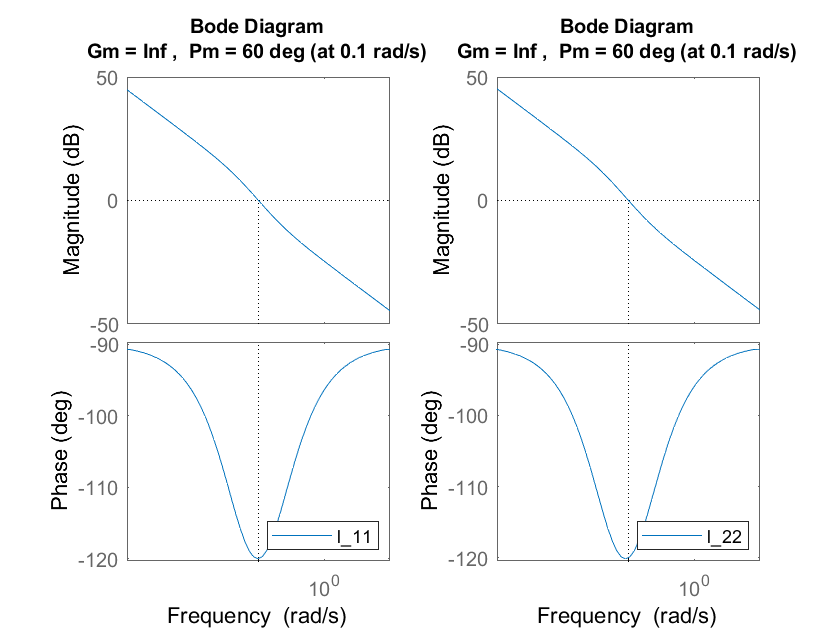

figure()
subplot(1,2,1)
margin(L_m(1,1))
legend('l_{11}', 'Location', 'southeast')
subplot(1,2,2)
margin(L_m(2,2))
legend('l_{22}', 'Location', 'southeast')


% Simulate system in simulink
F = F_m;
L = L_m;
G = G_m;
closedloop'

ans =      8     0     0     0     0     0     2


sim('closedloop')

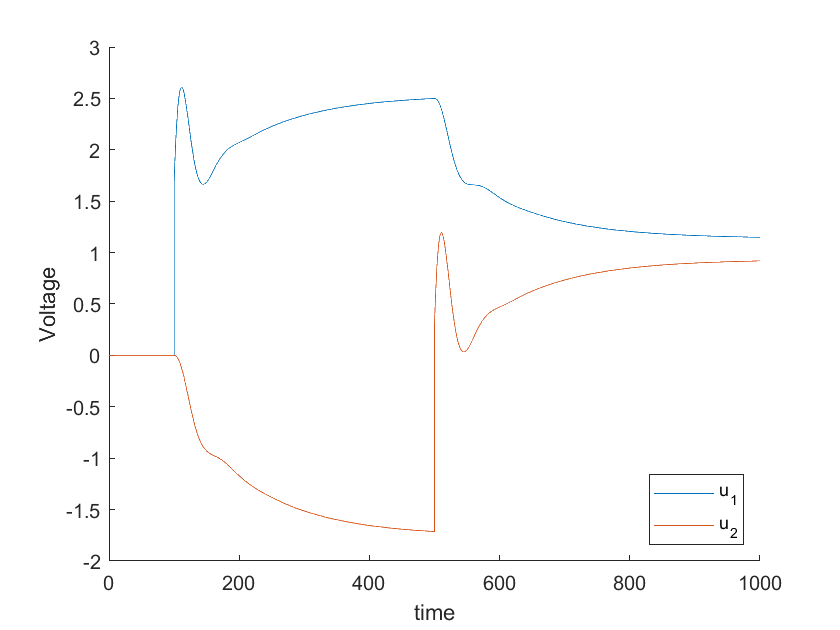

figure()
hold on
time_m = uout.Time;
u1_m =  uout.Data(:,1);
u2_m =  uout.Data(:,2);
plot(time_m, u1_m)
plot(time_m, u2_m)
legend('u_1', 'u_2','Location', 'southeast')
xlabel('time')
ylabel('Voltage')
hold off

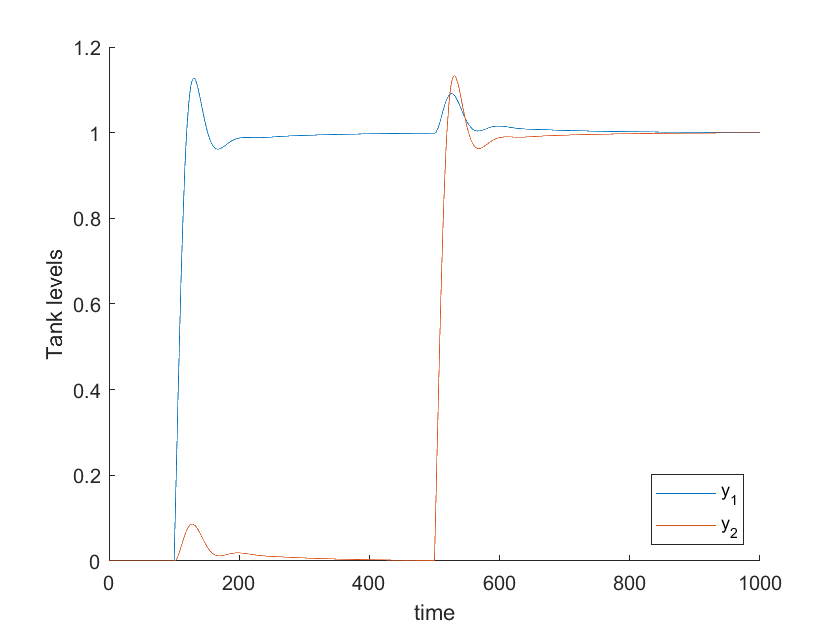

figure()
hold on
y1_m =  yout.Data(:,1);
y2_m =  yout.Data(:,2);
plot(time_m, y1_m)
plot(time_m, y2_m)
legend('y_1', 'y_2','Location', 'southeast')
xlabel('time')
ylabel('Tank levels')
hold off 

close_system

**Exercise 3.2.2**. Calculate the singular values of the sensitivity function

I = eye(2);
S_m = 1/(I+L_m);
T_m = I - S_m;

[U_S_m,S_S_m,V_S_m] = svd(evalfr(S_m,0))

U_S_m =      1     0
     0     1


S_S_m =      0     0
     0     0


V_S_m =      1     0
     0     1


[U_T_m,S_T_m,V_T_m] = svd(evalfr(T_m,0))

U_T_m =      1     0
     0     1


S_T_m =      1     0
     0     1


V_T_m =      1     0
     0     1


## **Yet again, now solve the above problems above for the non-minimum phase case**

**Exercise 3.2.1.** Design a decentralized controller by pairing inputs and outputs according

to the RGA analysis. The intended phase margin is 'm = $\phi_m$/3 and the crossover

frequency !c is 0.1 rad/s for the minimum phase case and 0.02 rad/s for the

non-minimum phase case. (To make sure that the problem is correctly solved, investigate

the Bode diagram of L.)

sys_nm = nonminphase

sys_nm =
 
  A = 
             x1        x2        x3        x4
   x1  -0.05106         0   0.08582         0
   x2         0  -0.04692         0   0.09089
   x3         0         0  -0.08582         0
   x4         0         0         0  -0.09089
 
  B = 
            u1       u2
   x1   0.1044        0
   x2        0  0.09038
   x3        0   0.1506
   x4    0.174        0
 
  C = 
        x1   x2   x3   x4
   y1  0.2    0    0    0
   y2    0  0.2    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.




% Desired phase and crossover freq
pm = pi/3;
wc_nm = 0.02;

s = tf('s');

G_nm = tf(sys_nm);

[~, ph_12_nm] = bode(G_nm(1,2), wc_nm);
[~, ph_21_nm] = bode(G_nm(2,1), wc_nm);

Ti_1_nm = 1/wc_nm*tan(-pi+pi/2+pm-ph_12_nm*pi/180);
Ti_2_nm = 1/wc_nm*tan(-pi+pi/2+pm-ph_21_nm*pi/180);

l12_nm = G_nm(1,2)*(1+1/(s*Ti_1_nm));
l21_nm = G_nm(2,1)*(1+1/(s*Ti_2_nm));

[l12_wc_nm, ~] = bode(l12_nm, wc_nm);
[l21_wc_nm, ~] = bode(l21_nm, wc_nm);

K1_nm = 1/abs(l12_wc_nm);
K2_nm = 1/abs(l21_wc_nm);

f1_nm = K1_nm*(1+1/(s*Ti_1_nm));
f2_nm = K2_nm*(1+1/(s*Ti_2_nm));

F_nm = [0, f1_nm; f2_nm, 0]

F_nm =
 
  From input 1 to output...
   1:  0
 
       0.6915 s + 0.1437
   2:  -----------------
            4.811 s
 
  From input 2 to output...
       0.5792 s + 0.1469
   1:  -----------------
            3.943 s
 
   2:  0
 
Continuous-time transfer function.



L_nm = minreal(G_nm*F_nm);

Plot the results

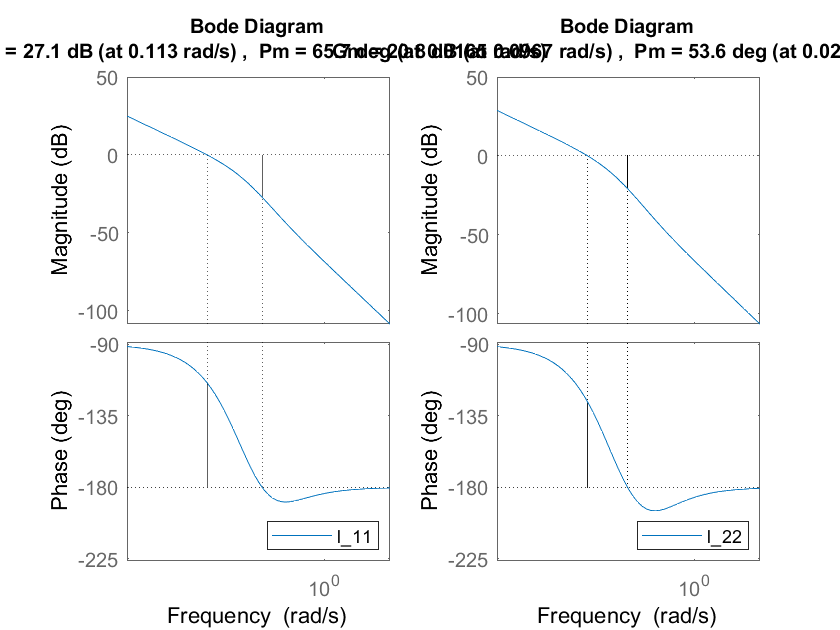

figure()
subplot(1,2,1)
margin(L_nm(1,1))
legend('l_{11}', 'Location', 'southeast')
subplot(1,2,2)
margin(L_nm(2,2))
legend('l_{22}', 'Location', 'southeast')


% Simulate system in simulink
F = F_nm;
L = L_nm;
G = G_nm;
closedloop
sim('closedloop')

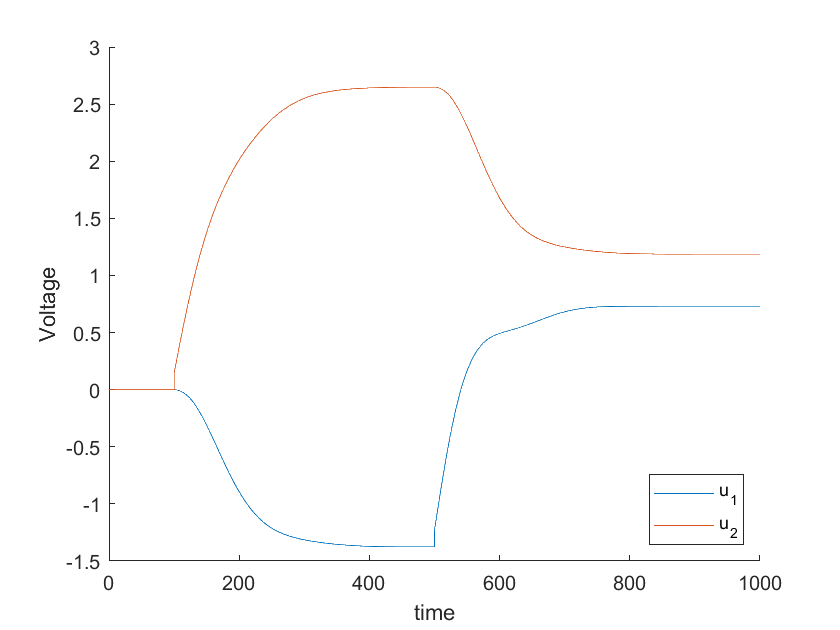

figure()
hold on
time_nm = uout.Time;
u1_nm =  uout.Data(:,1);
u2_nm =  uout.Data(:,2);
plot(time_nm, u1_nm)
plot(time_nm, u2_nm)
legend('u_1', 'u_2','Location', 'southeast')
xlabel('time')
ylabel('Voltage')
hold off

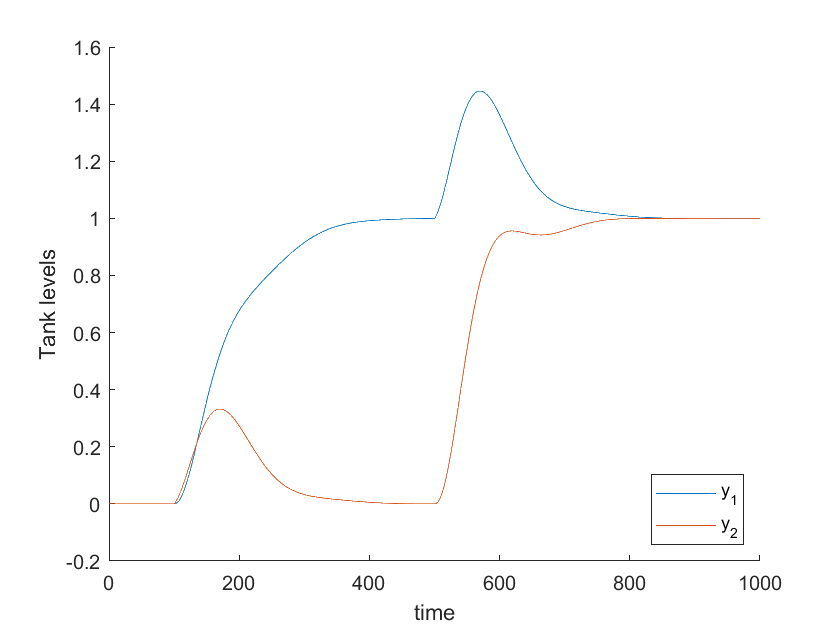

figure()
hold on
y1_nm =  yout.Data(:,1);
y2_nm =  yout.Data(:,2);
plot(time_nm, y1_nm)
plot(time_nm, y2_nm)
legend('y_1', 'y_2','Location', 'southeast')
xlabel('time')
ylabel('Tank levels')

close_system

**Exercise 3.2.2**. Calculate the singular values of the sensitivity function

I = eye(2);
S_nm = 1/(I+L_nm);
T_nm = I - S_nm;

[U_S_nm,S_S_nm,V_S_nm] = svd(evalfr(S_nm,0))

U_S_nm =      1     0
     0     1


S_S_nm =      0     0
     0     0


V_S_nm =      1     0
     0     1


[U_T_nm,S_T_nm,V_T_nm] = svd(evalfr(T_nm,0))

U_T_nm =      1     0
     0     1


S_T_nm =      1     0
     0     1


V_T_nm =      1     0
     0     1
